clear all
close all

kep1=imread("");
neg_kep=255-kep1;
kep=rgb2gray(kep1);
kep=im2double(kep);
kep=imgaussfilt(kep,1);

[magassag,szelesseg]=size(kep);

szelesseg_valos=8; %prototípus szélesség: 8 cm
pixel_to_cm=szelesseg_valos/szelesseg;

[x,y]=find(kep==max(kep(:)));
pozicio_legsotetebb=[x,y];

neg_kep=rgb2gray(neg_kep);
neg_kep=im2double(neg_kep);
neg_kep=imgaussfilt(neg_kep,3);

[X,Y]=find(neg_kep==max(neg_kep(:)));
pozicio_legvilagosabb=[X,Y];

tavolsag_pix=sqrt((X-x)^2+(Y-y)^2);
tavolsag_cm=tavolsag_pix*pixel_to_cm

tavolsag_cm = 4.0085

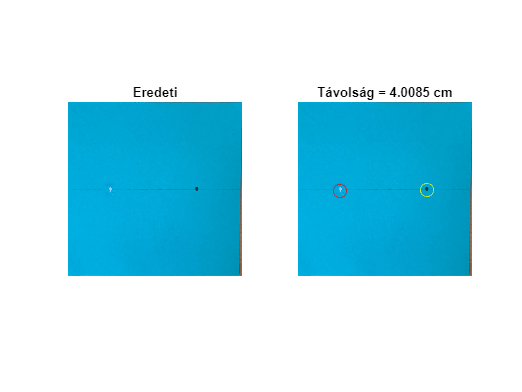


figure()
subplot(121)
imshow(kep1)
title("Eredeti");
subplot(122)
imshow(kep1);
hold on
plot(y, x, "ro", "MarkerSize", 10);
hold off
hold on
plot(Y, X, "yo", "MarkerSize", 10);
hold off
title(["Távolság = ", num2str(tavolsag_cm), " cm"]);